MEAM-5430 HW6

Problem 1

1c

clear;
clc;

c_d0 = 0.007;
r = 0.001;
S = 0.25;  % wing area
span = 1.2;
chord = S / span

chord = 0.2083

AR = span / chord

AR = 5.7600

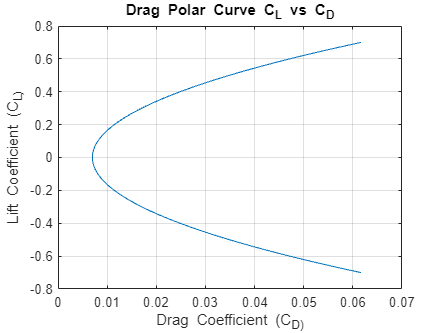


e = 0.9;  % wing span efficiency
rho = 1.225;
W_O = 5.5 * 9.8;
W = W_O;

% plot drag polar
C_L_values = linspace(-0.7, 0.7, 200);
C_D_values = arrayfun(@(C_L) CD_CL(C_L), C_L_values);

figure;
plot(C_D_values, C_L_values);
xlabel('Drag Coefficient (C_D)');
ylabel('Lift Coefficient (C_L)');
title('Drag Polar Curve C_L vs C_D');
grid on;

1d

% Compute cruise speed drag
v = 40;
C_L = 2 * W_O / rho / S / v^2;
C_D = CD_CL(C_L);
D = 0.5 * C_D * rho * S * v^2

D = 3.0375

P_req = D * v

P_req = 121.4982

1e

v_x = 100 * 1.6 / 3.6;
C_Lx = sqrt(c_d0/(r + 1 / pi / e / AR))

C_Lx = 0.3349

C_Dx = CD_CL(C_Lx)

C_Dx = 0.0195

S_x = 2 * W_O / C_Lx / rho / v_x^2

S_x = 0.1330

1f

C_L_land = 1.44;
v_land = sqrt(2 * W_O / rho / S_x / C_L_land)

v_land = 21.4344

s_rwy = 60.96;  % runway length
a_land = v_land^2 / 2 / s_rwy

a_land = 3.7683

1g

% estimated MoI
I = 1 / 12 * (2.5 * 0.9^2 + 1.5 * 0.2^2 + 1.5 * 0.3^2)

I = 0.1850

function C_D = CD_CL(C_L)
    c_d0 = 0.007;
    r = 0.001;
    span = 1.6;
    chord = 0.5;
    AR = span / chord;
    e = 0.9;  % wing span efficiency
    C_D = c_d0 + (r + 1 / pi / e / AR) * C_L^2;
end